1.

x=linspace(-2,2,100);
f=@(x) sin(x);
d=@(x) tan(x);
format long
bisection(f,2,4,.00001,100) 

ans =    3.141593933105469


%3.14159
bisection(d,1,2,.001,100)

ans =    1.571289062500000


%The root is suspected where there is a vertical asymptote

2.

fzero(@sin, [2 4])

ans =    3.141592653589793


fzero(@tan, [1 2])

ans =    1.570796326794897


fzero(@tan, [1 2], optimset('Display','iter'))

 
 Func-count    x          f(x)             Procedure
    2               1       1.55741        initial
    3               2      -2.18504        interpolation
    4         1.85165      -3.46644        interpolation
    5         1.41615        6.4146        bisection
    6         1.47895       10.8572        interpolation
    7          1.6339      -15.8261        bisection
    8         1.61954      -20.4982        interpolation
    9         1.58798      -58.1765        bisection
   10         1.55642       69.5775        bisection
   11         1.55783       77.1347        interpolation
   12         1.56502       173.074        bisection
   13         1.56861       457.679        bisection
   14          1.5722      -710.251        bisection
   15         1.57182       -980.91        interpolation
   16         1.57041       2574.06        bisection
   17         1.57111      -3169.73        interpolation
   18         1.57104      -4124.11        interpolation
   19         

ans =    1.570796326794897


fzero(@sin, [3 4], optimset('PlotFcns',@optimplotfval));
bisection(f,2,4,.001,100,'iter')

Func-count   x        f(x)
   1         3.000     0.141120
   2         3.500     -0.350783
   3         3.250     -0.108195
   4         3.125     0.016592
   5         3.188     -0.045891
   6         3.156     -0.014657
   7         3.141     0.000968
   8         3.148     -0.006845
   9         3.145     -0.002939
  10         3.143     -0.000985

ans =    3.141601562500000


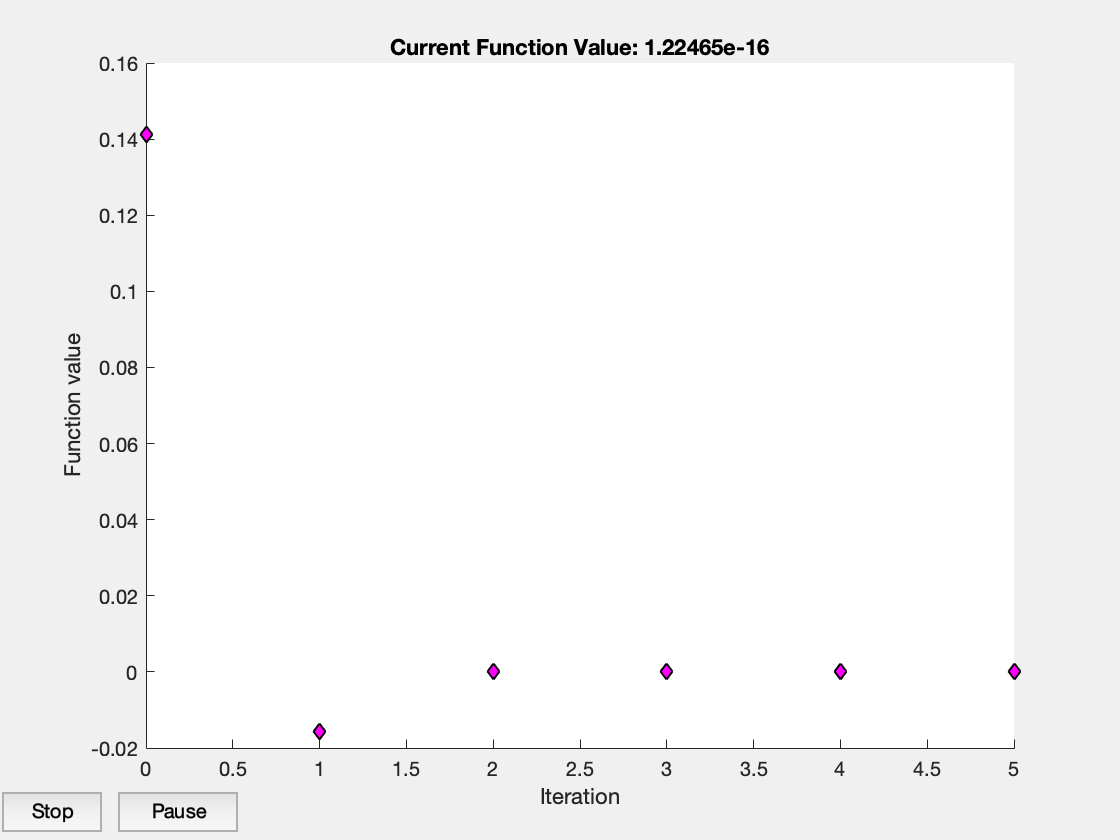

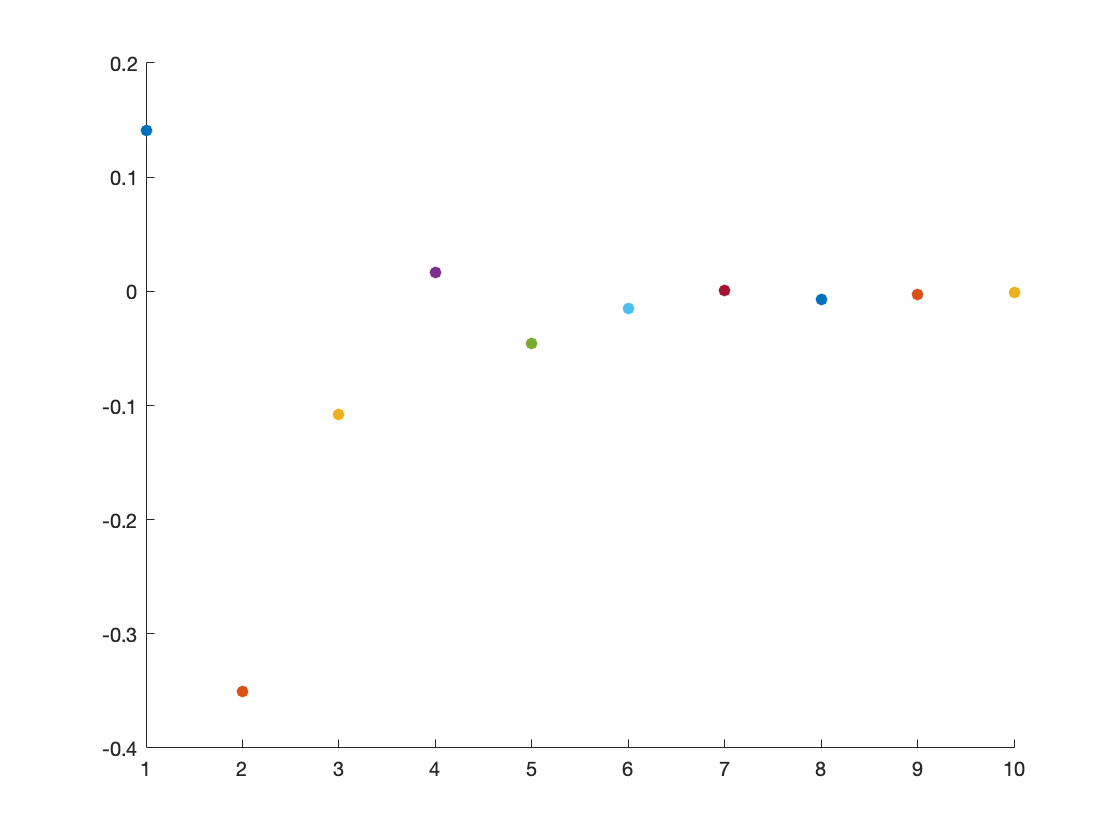

ans =    3.141601562500000


bisection(f,2,4,.001,100,'plot')

function p = bisection(f, a, b, tol, maxits, varargin)
options = [0 0];
if (~isempty(varargin))
    for c=1:length(varargin)
                switch varargin{c}
                case {'plot'}
                    options(1)=1;

                case {'iter'}
                    options(2)=1;
                    fprintf("Func-count   x        f(x)")
            end
    end
end
for i=1:maxits
    assert(sign(f(a)) ~= sign(f(b)));
    c=(a+b)/2; %midpoint of interval
    
    if(b-a)/2<tol
       p=c;
       return;
    end

    if sign(f(a)) ~= sign(f(c))
        %root is left subinterval
        %fprintf('root is in the left subinterval\n');
        b=c; %a stays same
    else
        %root is right subinterval
        a=c; %b stays same
       %fprintf('root is in the right subinterval\n');
    end
    if(options(2)==1)
        formatSpec = '\n%4.0f      %8.3f     %1f';
        fprintf(formatSpec,i,c,f(c))
    end
    if (options(1)==1) 
        hold on
        figure(2)
        scatter(i,f(c), 'filled')
        hold off
    end
    
end
p=c;
    
end